Zayid Oyelami

Problem Set 3

March 21 2019

## Problem 1

% Load all data points 
allFiles = dir('code/dat/107*.pts');
N = length(allFiles);
for i=1:N
  [X(:,:,i),Y(:,:,i),ptSets(:,:,i)] = readPoints( strcat('code/dat/',allFiles(i).name ) );
end

### Original Set of Faces

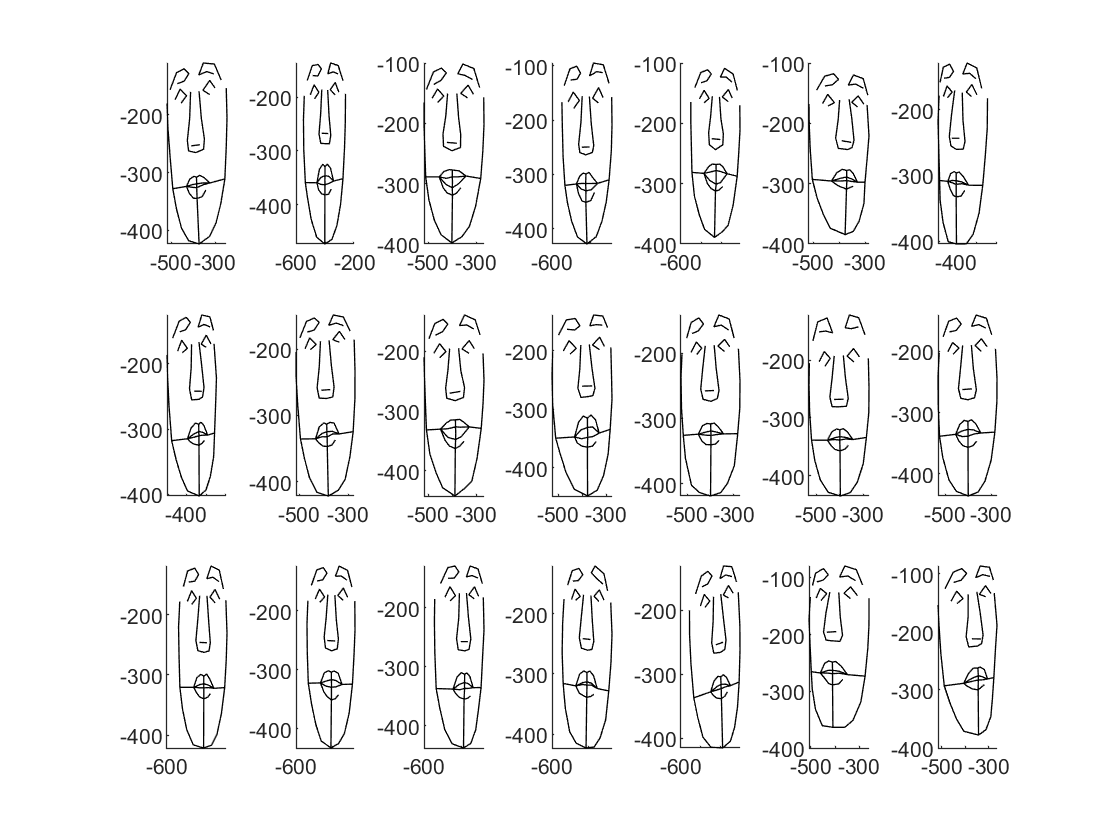

figure()
for j = 1:N
    subplot(3,7,j)
    drawFaceParts( -ptSets(:,:,j), 'k-' )
end

### Aligning Faces


for iter = 1:500
    if iter == 1
        mu = ptSets(:,:,1);
    else
        [aligned(:,:,1), pars,E(1)] = getAlignedPts(ptSets(:,:,1),mu);
        mu = aligned(:,:,1);
    end
    for i = 1:N
        [aligned(:,:,i), pars,E(i)] = getAlignedPts(mu,ptSets(:,:,i));
    end
    mu = mean(aligned,3);
    energy(iter) = mean(E);
end

### Energy Calculations

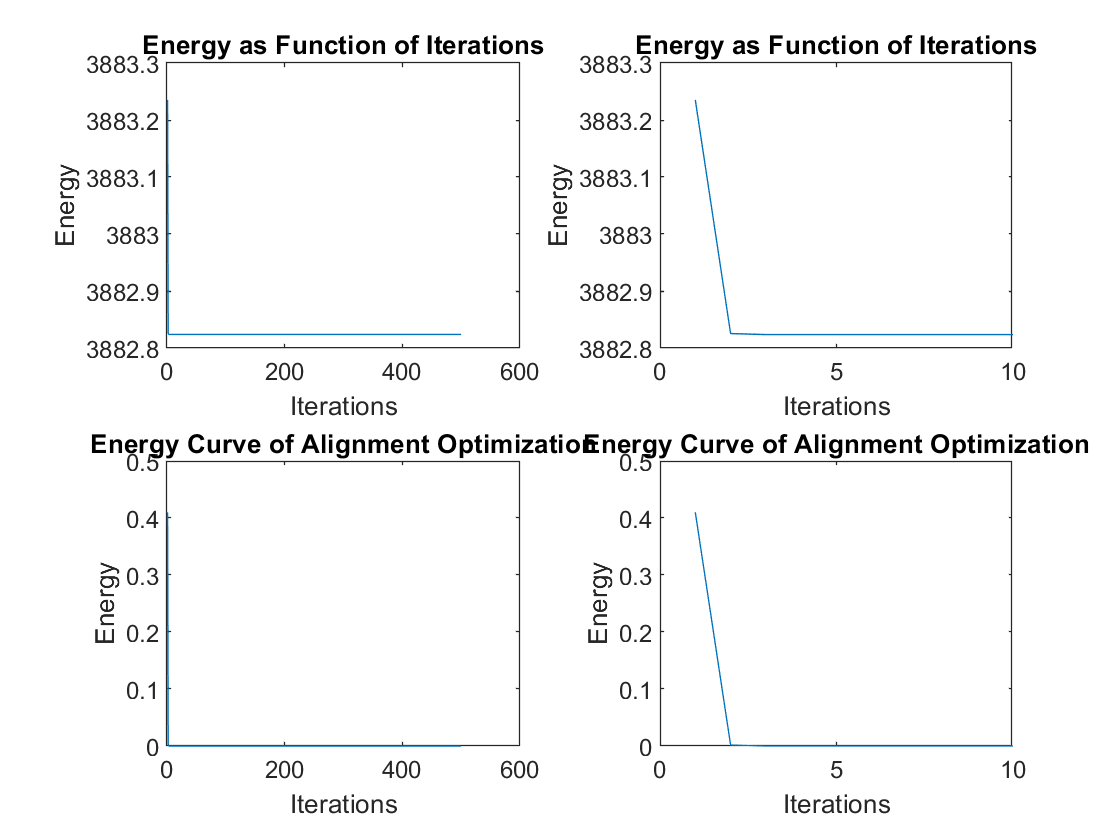

figure()
subplot(2,2,1)
plot(energy)
title('Energy as Function of Iterations')
ylabel('Energy')
xlabel('Iterations')
subplot(2,2,2)
plot(energy(1:10))
title('Energy as Function of Iterations')
ylabel('Energy')
xlabel('Iterations')
subplot(2,2,3)
plot(abs(diff(energy)))
title('Energy Curve of Alignment Optimization')
ylabel('Energy')
xlabel('Iterations')
subplot(2,2,4)
e = abs(diff(energy));
plot(e(1:10))
title('Energy Curve of Alignment Optimization')
ylabel('Energy')
xlabel('Iterations')

### Aligned Faces

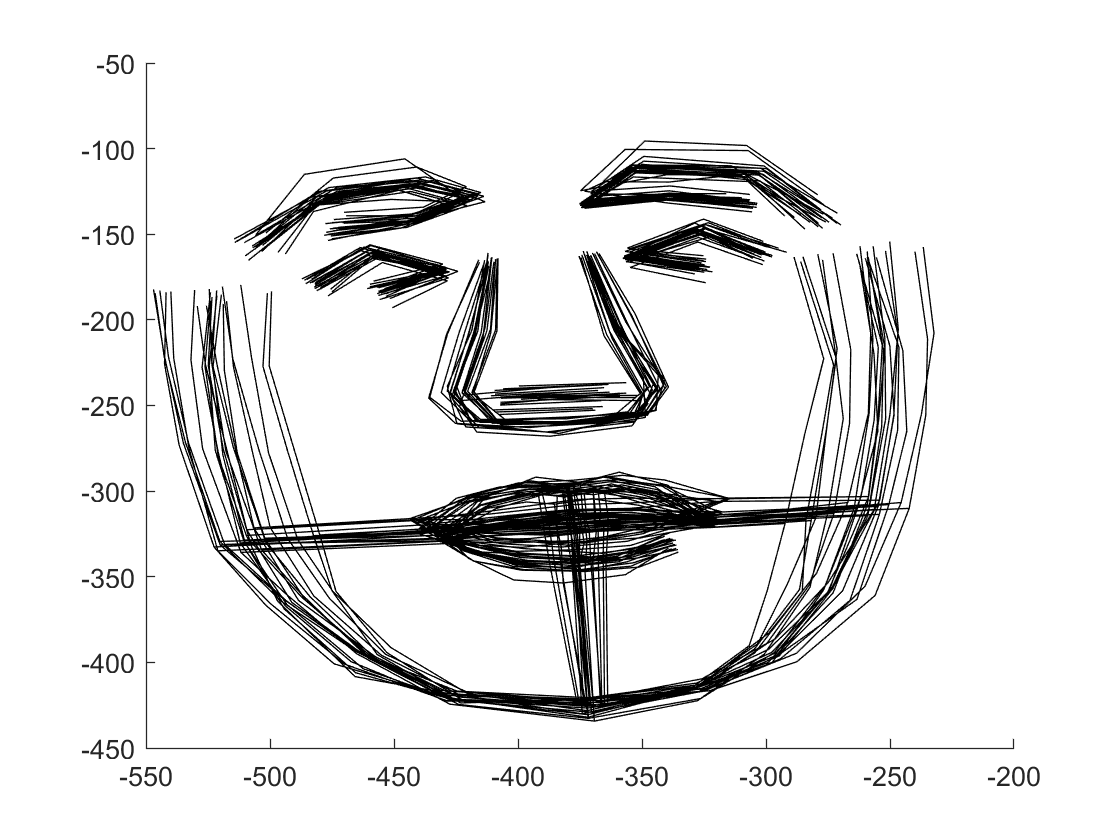

figure()
for j = 1:N
    drawFaceParts( -aligned(:,:,j), 'k-' )
    hold on
end

## Problem 2

% Reformatting the shape of the point sets to be a vector on n points of
% the ith shape in the set
for i =1:N
    P(:,i) =reshape(aligned(:,:,i),1,136);
end
% Taking the mean across points N = 136 eqn 7 Cootes
muP = mean(P,2);
% Calculating the deviation from mean across points N = 136 eqn. 8 (Cootes)
dP = P-muP;
% Calculate 2n x 2n Covariance Matrix eqn. 9 (Cootes)
S = zeros(136,136,21);
for i = 1:N
    S(:,:,i) = dP(:,i)*dP(:,i)';
end
Smu = mean(S,3);


$$Sp_k = \lambda_kp_k$$


The eigenvector with the most variation explains the most significant modes of variation in the variables. Using the PCA function of Matlab, the largest eigenvectors were found.

[coeff,score,latent,explained] =pca(Smu);

score(1:3)

ans =  -661.1122 -566.3378 -600.7431


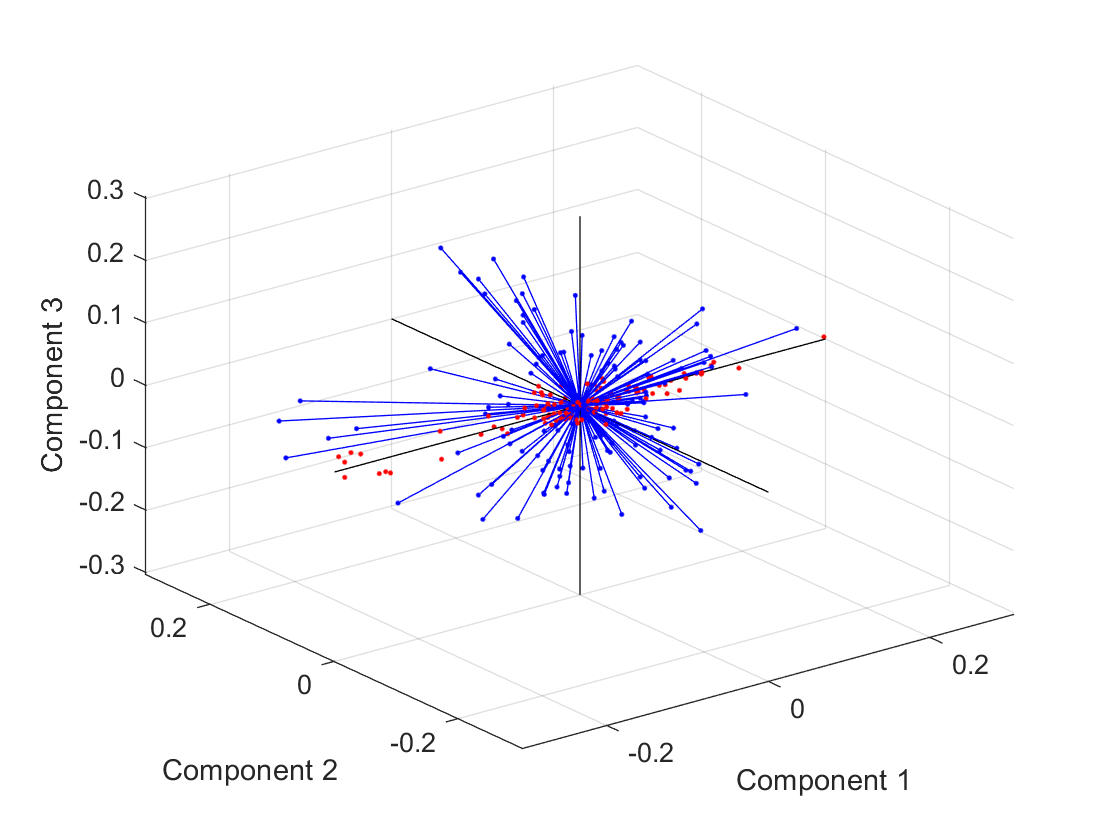

figure()
biplot(coeff(:,1:3),'scores',score(:,1:3))

covarianceMatrix = cov(Smu);
[V,D] = eig(covarianceMatrix);
[bs,ind]=maxk(diag(D),3)

bs = 	1.0e+04 *

    4.3277
    0.1508
    0.0460


ind =    136
   135
   134


maxEigV = V(:,ind);

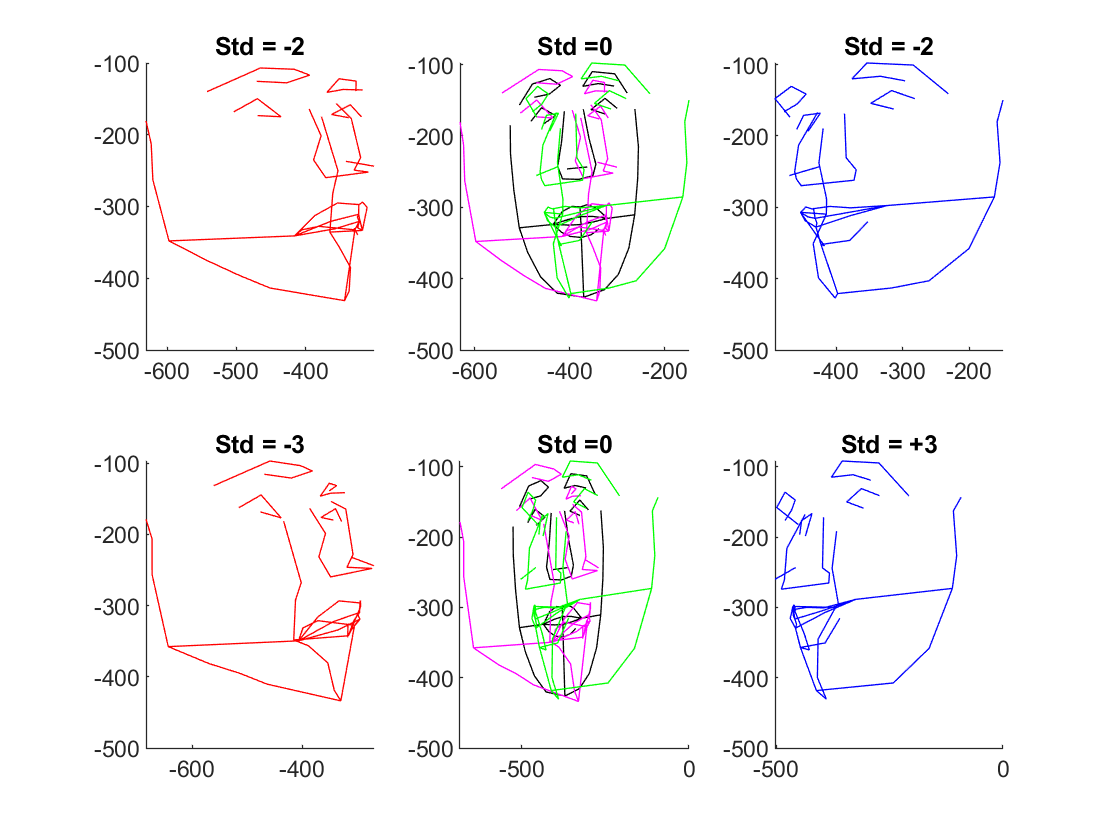

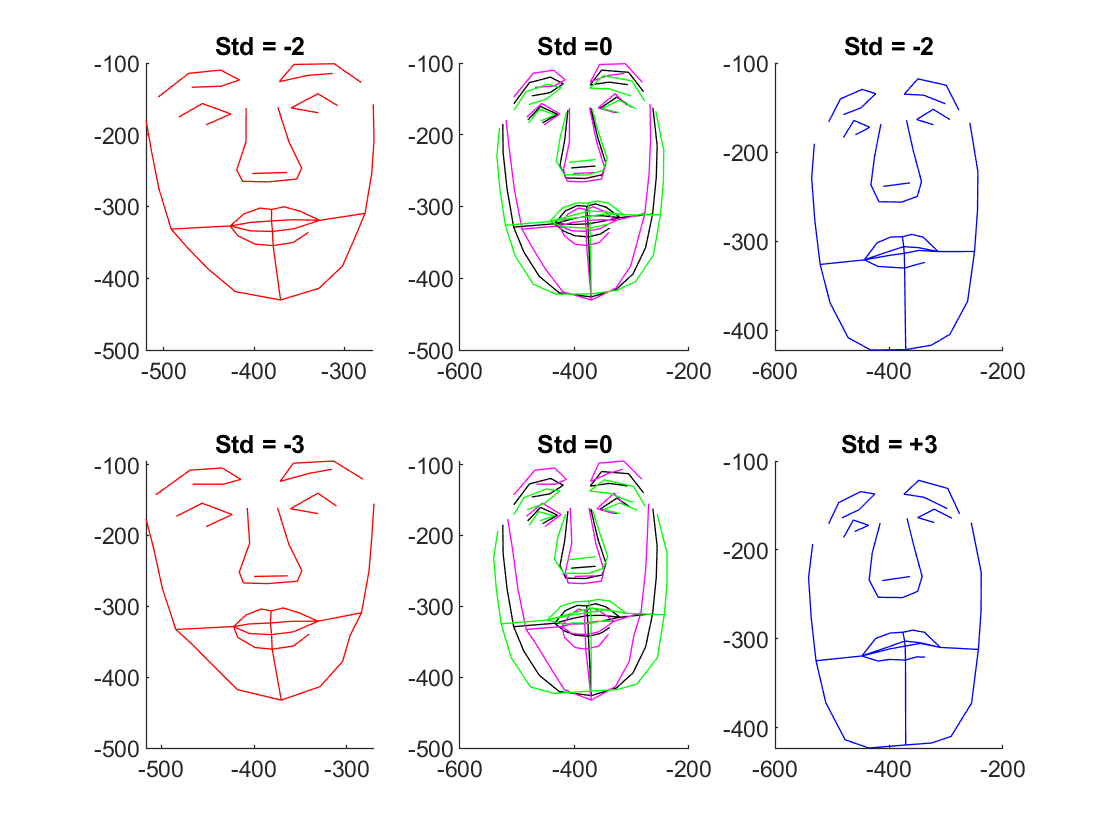

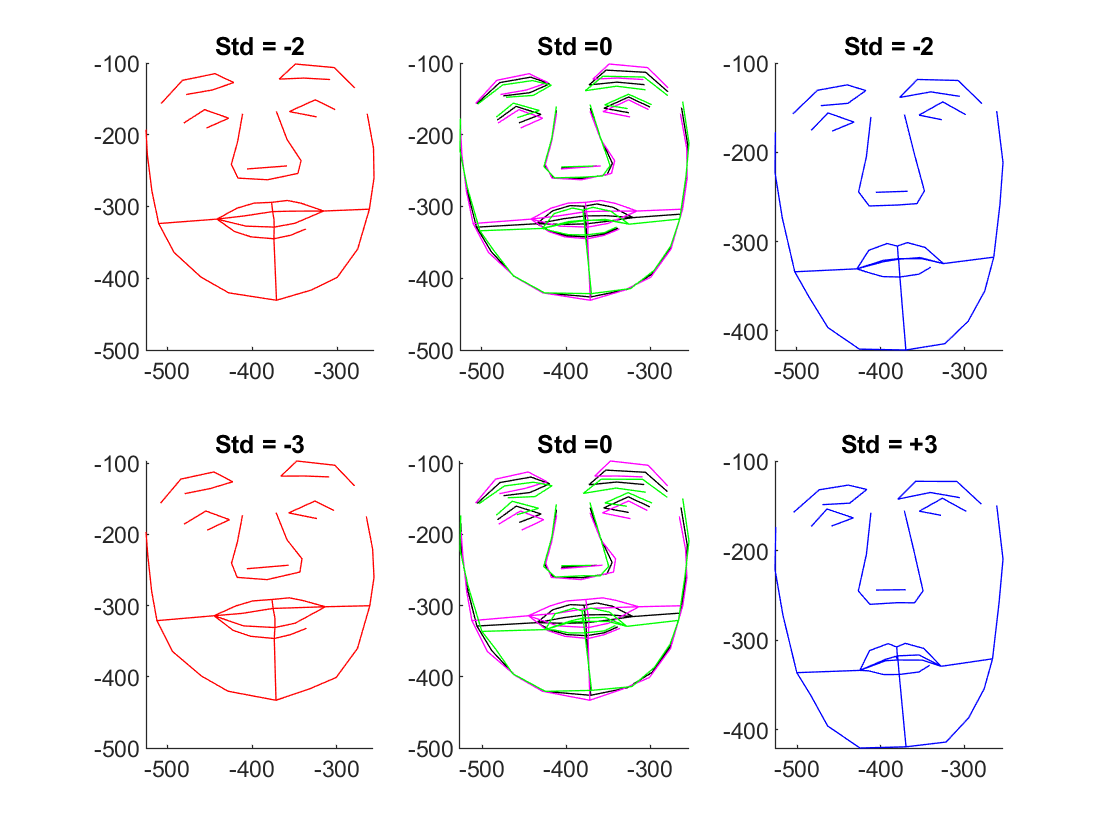

for i = 1:3
    eigFaces(maxEigV(:,i),bs(i),muP);
end

The differences between the faces occur especially when the deviation is at +/- 3 and mostly for the largest eigenvector, which would be sensible because it explains the most variation.

We are operating within the bounds of $-3\sqrt{\lambda_k }\le b_k \le \;3\sqrt{\lambda_k }$.

function eigFaces(eig,bk,muP)
    bmin = -3.*sqrt(abs(bk)');
    xmin = muP + eig*bmin;
    xminr = reshape(xmin,68,2);
    
    bmin = -2.*sqrt(abs(bk)');
    xmin = muP + eig*bmin;
    xmin2r = reshape(xmin,68,2);
    
    bmax = 2.*sqrt(abs(bk)');
    xmax = muP + eig*bmax;
    xmax2r = reshape(xmax,68,2);
    
    bmax = 3.*sqrt(abs(bk)');
    xmax = muP + eig*bmax;
    xmaxr = reshape(xmax,68,2);
    
    xmu = reshape(muP,68,2);

    figure()
    subplot(2,3,1)
        drawFaceParts( -xmin2r, 'r-' )
        title('Std = -2')
    subplot(2,3,2)
        drawFaceParts( -xmu, 'k-' )
        title('Std =0')
        hold on
        drawFaceParts( -xmin2r, 'm-' )
        drawFaceParts( -xmax2r, 'g-' )
    subplot(2,3,3)
        drawFaceParts( -xmax2r, 'b-' )
        title('Std = -2')
    subplot(2,3,4)
        drawFaceParts( -xminr, 'r-' )
        title('Std = -3')
    subplot(2,3,5)
        drawFaceParts( -xmu, 'k-' )
        title('Std =0')
        hold on
        drawFaceParts( -xminr, 'm-' )
        drawFaceParts( -xmaxr, 'g-' )
    subplot(2,3,6)
        drawFaceParts( -xmaxr, 'b-' )
        title('Std = +3')
end

